# Code for manuscript "A thermodynamic framework for modelling membrane transporters using bond graphs"

## Enzyme cycle (Figure 1)

A passive transporter can be modelled using the enzyme cycle


$$\mathrm{E_1 + S_i \rightleftharpoons E_2} \\\mathrm{E_2 \rightleftharpoons E_2 + S_e}$$


In the code below, we simulate a transporter modelled as an enzyme cycle, and demonstrate that the transporter reaches a steady state. The direction of steady-state transport is dictated by the concentration gradient of the substrate.

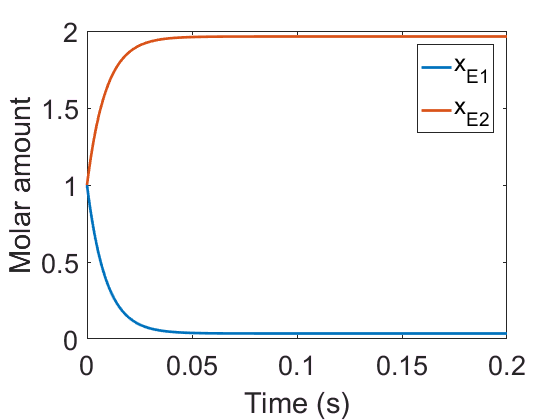

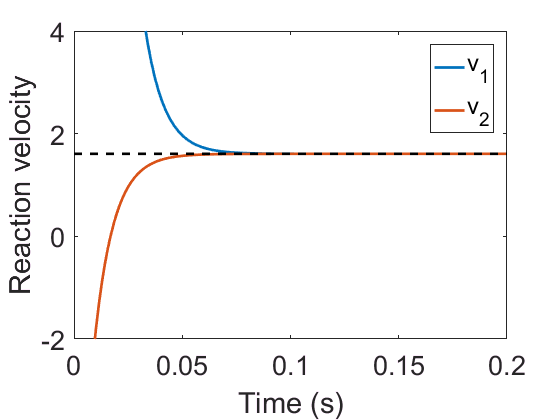

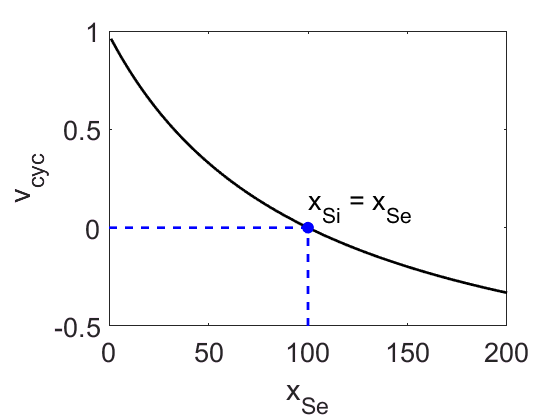

enzyme_cycle_sim

## Coupled transport (Figure 2)

In order for a transporter to move a substrate against a concentration gradient, it must couple the transport to a process that generates sufficient energy for the transport to occur. Here we model a transporter that couples the transport of substrate to another biochemical reaction using the reaction scheme


$$\mathrm{E_1 + S_i \rightleftharpoons E_2} \\
\mathrm{E_2 + A \rightleftharpoons E_3} \\
\mathrm{E_3  \rightleftharpoons E_4  + S_e} \\ \mathrm{E_4  \rightleftharpoons E_1 + B}$$


which has the overall reaction


$$	\mathrm{S_i} + A \rightleftharpoons \mathrm{S_e} + B$$


In the code below, we simulate this system to steady state. The plots show that the amount of A affects the ability of the transporter to move a substrate against a chemical gradient. By modelling this system as a bond graph, fundamental thermodynamic constraints are captured, therefore the pump only operates in the direction of decreasing chemical potential, and stops cycling at equilibrium

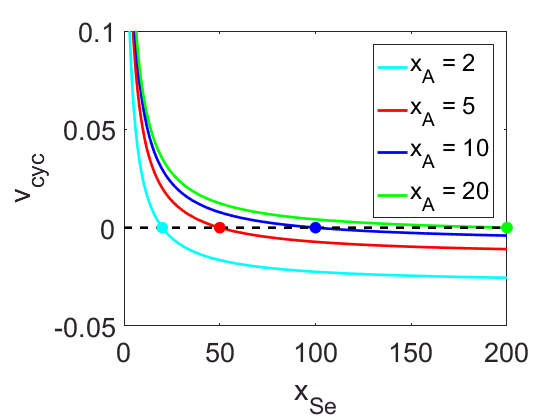

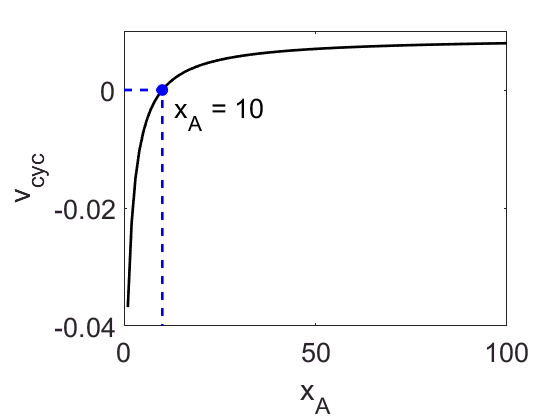

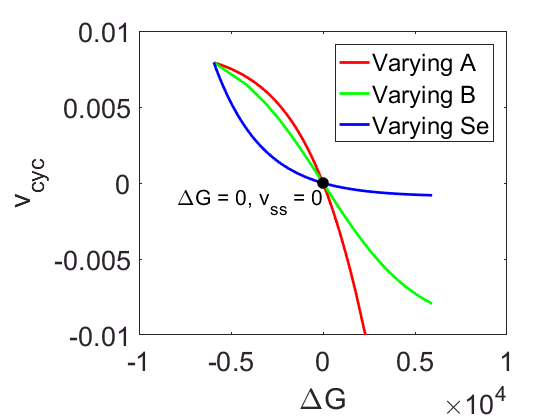

coupled_reactions_sim

## Electrogenic transport (Figure 3)

Many transporters, including ion transporters, move charged species across a membrane that is charged. For these transporters, the membrane potential contributes to the thermodynamics and kinetics of the system. Because bond graphs are domain-independent, they are able to model the interaction between chemical and electrochemical power in electrogenic systems. Here we simulate the transporter model


$$\mathrm{E_1 + S_i^+ \rightleftharpoons E_2} \\\mathrm{E_2 \rightleftharpoons E_2 + S_e^+}$$


where the substrate is charged. As seen in the plots below, the bond graph model captures the equilibrium point (Nernst potential) of this transporter.

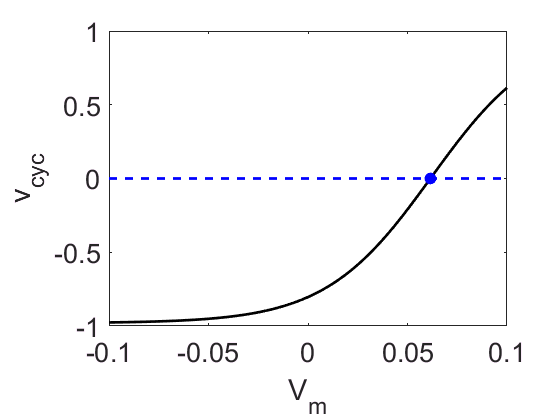

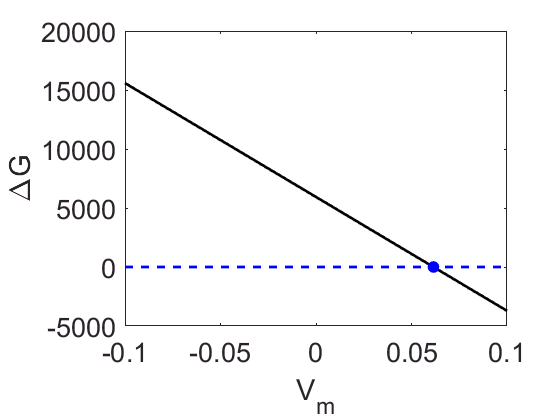

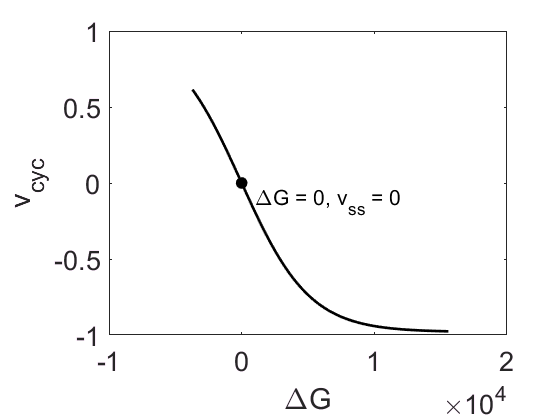

charged_species_sim

## SERCA bond graph parameters

The script  below calculates the bond graph parameters for the SERCA model of Tran et al. (2009), using the kinetic parameters and stoichiometric matrix.

SERCA_bg_parameters

k

k =    1.0e+18 *

    0.0000
    0.0000
    0.0024
    0.0000
    0.0000
    0.0000
    2.4667
    0.0000
    0.0000
    0.0000


M

M =      1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     2     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     2     0     0

kappa

kappa =    1.0e+07 *

    0.0000
    0.0002
    0.8327
    0.0002
    0.0003
    0.0131
    1.1613
    1.1613
    0.0000


K

K =    1.0e+07 *

    0.0005
    0.0004
    0.0003
    1.6521
    0.0000
    0.0993
    0.0000
    0.0002
    0.0000
    0.0002


## SERCA simulations (Figure 5)

The code below generates the plots for Figure 5, which show that the bond graph model of SERCA reproduces the behaviour of the kinetic model, and also allows for the calculation of energetic quantities such as free energy of reaction, power consumption and efficiency.

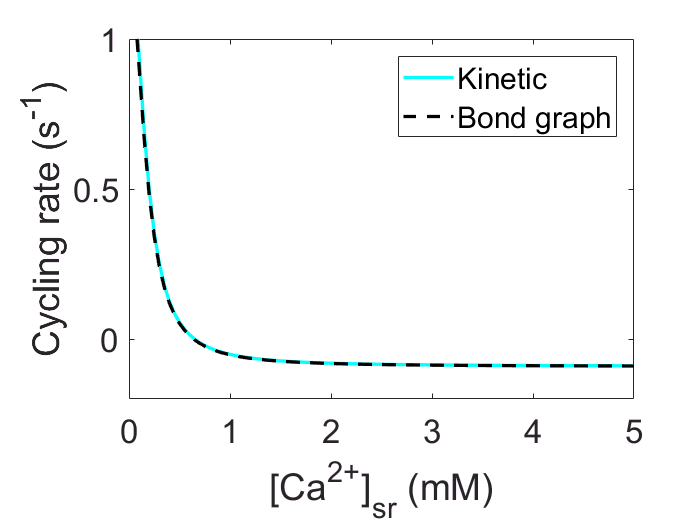

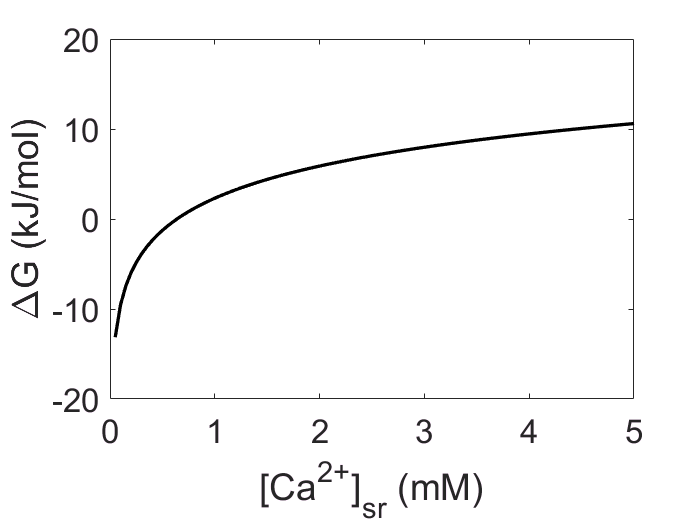

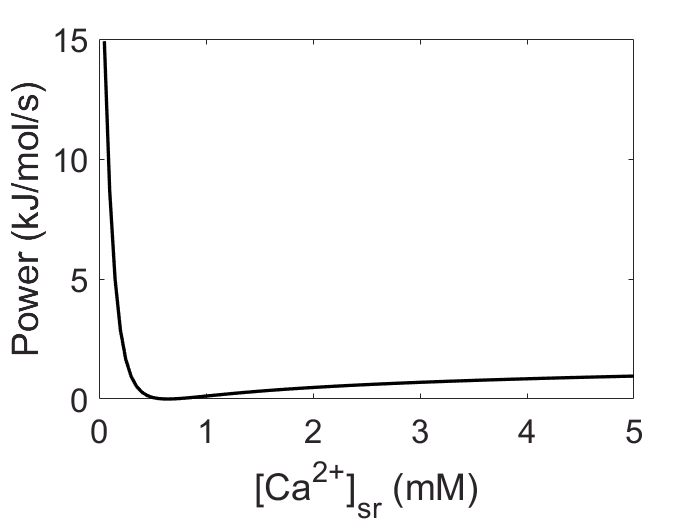

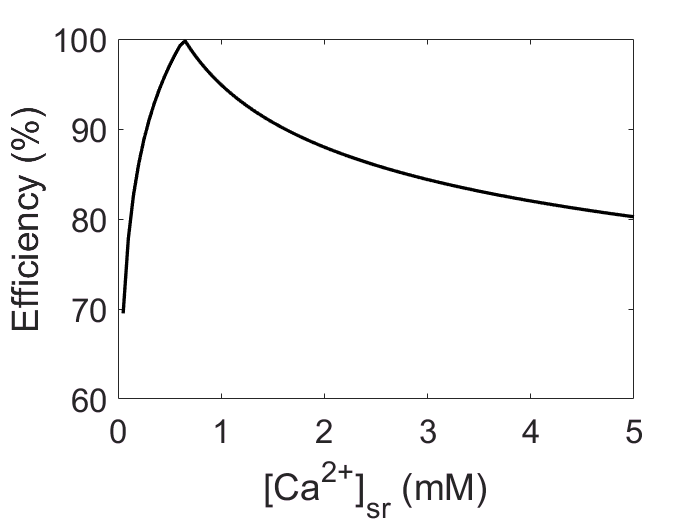

SERCA_sim

## Updated Na+/K+ ATPase parameters (Figures 7,8)

In the manuscript, we outlined corrections to the equations of the Na+/K+ ATPase model in Terkildsen et al. (2007) to make it thermodynamically consistent. In the code below, we re-fit the updated equations to the data to generate the plots for Figures 7 and 8.

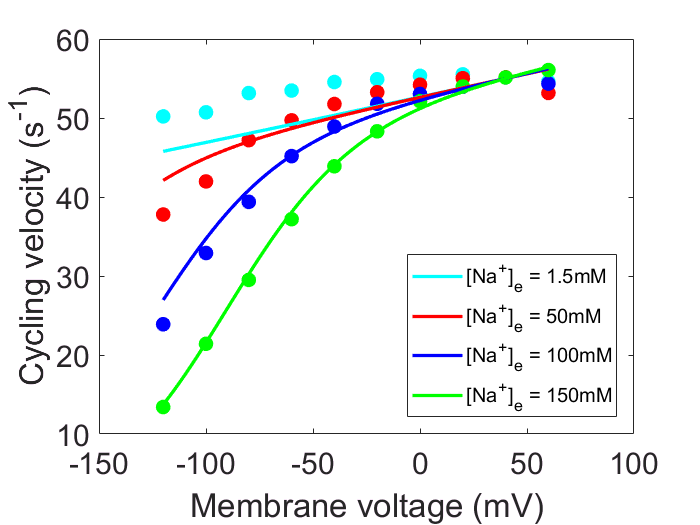

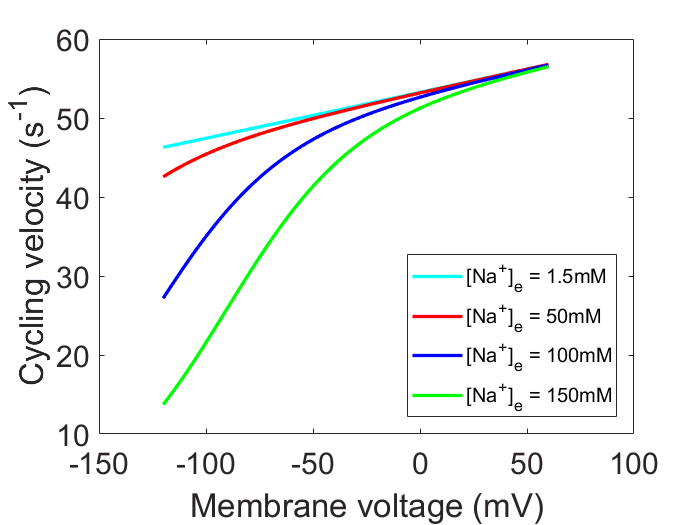

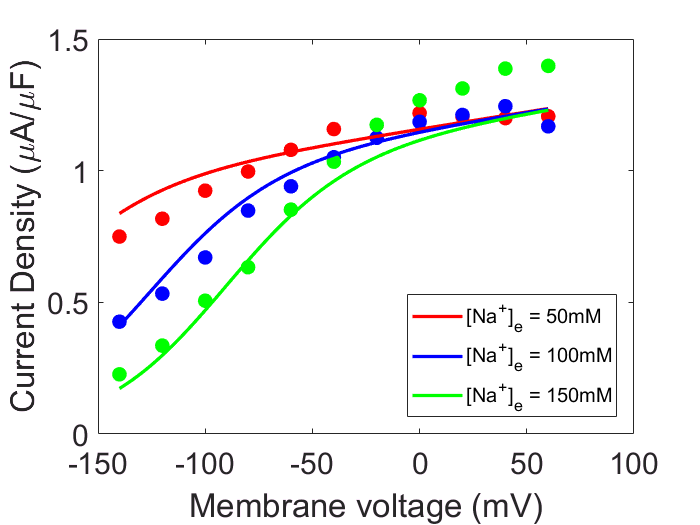

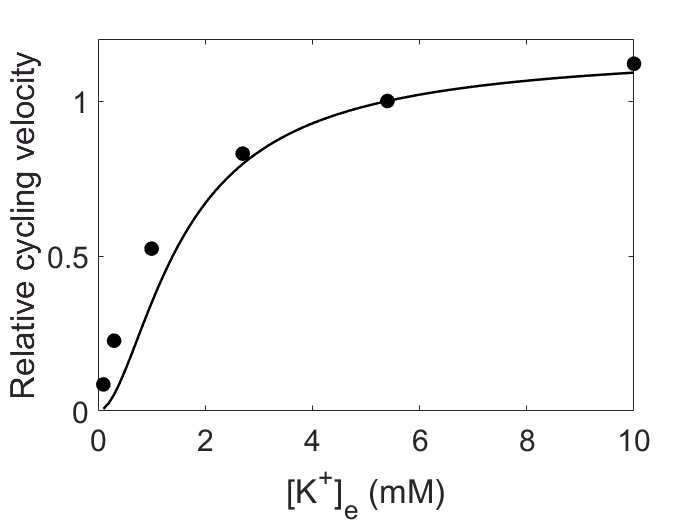

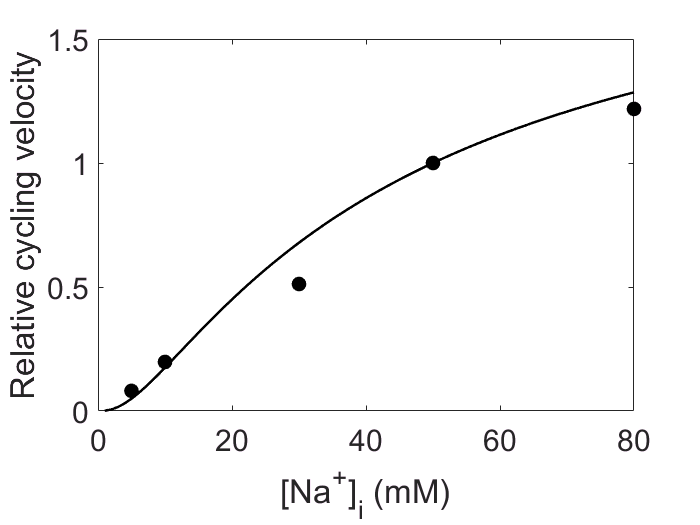

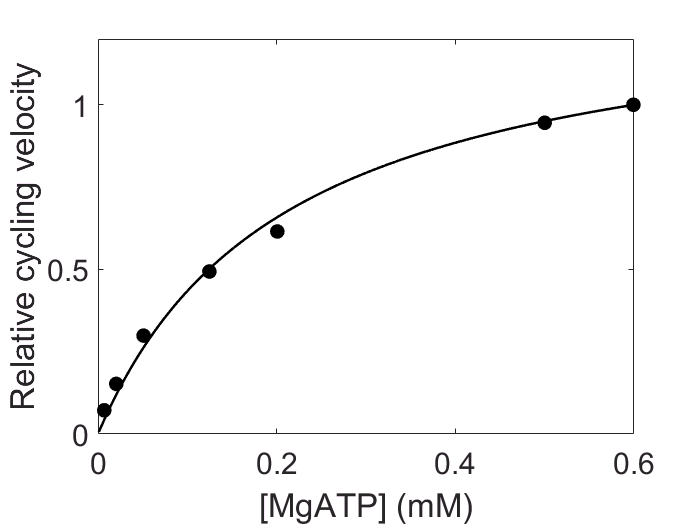

fit_NaK_parameters

params_vec

params_vec =    1.0e+06 *

    0.0006    0.0000    0.0000    0.0106    0.0000    0.0001    0.0014    0.0116    0.0002    0.0306    0.0364    0.2810    1.5740   -0.0000    0.0014


## Na+/K+ ATPase bond graph parameters

Because the updated model of Na+/K+ ATPase is thermodynamically consistent, it can be represented as a bond graph. In the code below, we use the fitted kinetic parameters to determine parameters for the bond graph model.

NaK_bg_parameters

k_mod

k_mod =    1.0e+10 *

    3.3590
    0.8397
    0.0001
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    2.1234
    0.5308


M_mod

M_mod =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0    

kappa

kappa =    1.0e+06 *

    0.0003
    0.1329
    0.2004
    2.2388
    0.0108
    0.0000
    0.0000
    0.0000
    0.0015
    0.2595


K

K =    1.0e+08 *

    1.0162
    0.0006
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0002
    0.1379
    0.0002


## Na+/K+ ATPase simulations (Figure 9)

In the code below, we simulate the bond graph model of Na+/K+ ATPase, showing that it reproduces the behaviour of the kinetic model. The bond graph model captures the correct equilibrium points, and complies with fundamental thermodynamic constraints.

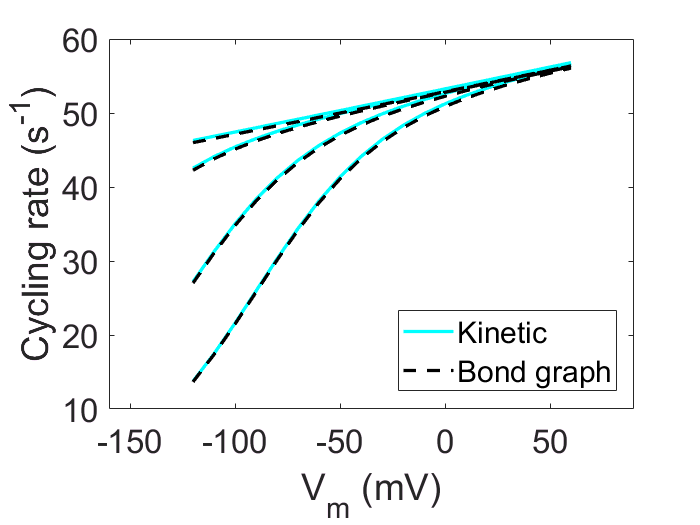

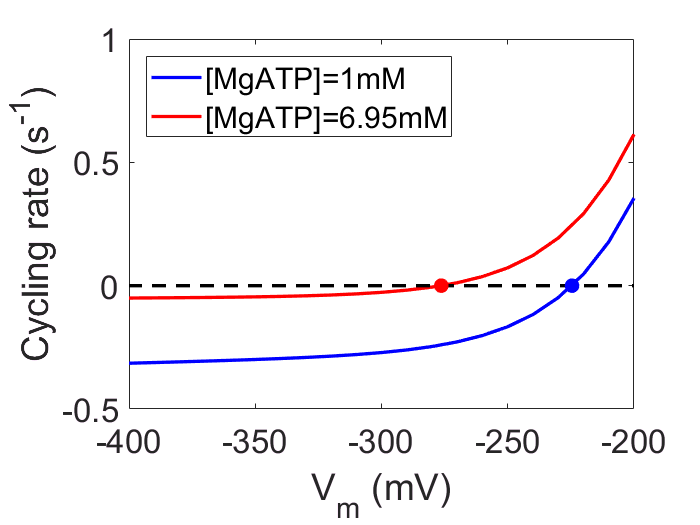

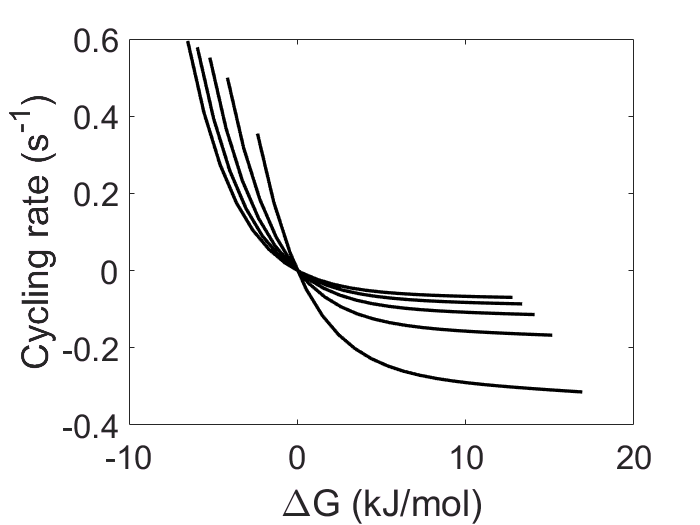

NaK_sim